clc;
clear;
close all;

tic;                              %程序运行计时
E0=0.001;                        %允许误差
MaxNum=100;                    %粒子最大迭代次数
narvs=3;                         %目标函数的自变量个数
particlesize=30;                    %粒子群规模
c1=0.8;                            %每个粒子的个体学习因子，也称为加速常数
c2=0.8;                            %每个粒子的社会学习因子，也称为加速常数
w=0.6;                           %惯性因子
vmax=0.5;                        %粒子的最大飞翔速度
x=rand(particlesize,narvs);     %粒子所在的位置
v=0.8*rand(particlesize,narvs);         %粒子的飞翔速度

h=0.01;
t0=0;
T=100;
n=(T-t0)/h;
y0=[2;-1;1];

%exact solution 
alpha=[0.9,0.85,0.95];
param=[1,0.1,1];
f_fun=@(t,y,par)([y(3)+(y(2)-par(1))*y(1);1-par(2)*y(2)-y(1)^2;-y(1)-par(3)*y(3)]);
J_fun=@(t,y,par)([-par(1),y(1),1;...
    -2*y(1),-par(2),0;...
    -1,0,-par(3)]);
[~,y_exact]=FDE_PI1_Im(alpha,f_fun,J_fun,t0,T,y0,h,param);

%the generated solution
y_pred=containers.Map();
for i=1:particlesize
    alpha=[x(i,1),x(i,2),x(i,3)];
    param=[1,0.1,1];
    f_fun=@(t,y,par)([y(3)+(y(2)-par(1))*y(1);1-par(2)*y(2)-y(1)^2;-y(1)-par(3)*y(3)]);
    J_fun=@(t,y,par)([-par(1),y(1),1;...
    -2*y(1),-par(2),0;...
    -1,0,-par(3)]);
    [~,y_p]=FDE_PI1_Im(alpha,f_fun,J_fun,t0,T,y0,h,param);
    y_pred(strcat(i))=y_p;
end

fitness = @(y)(norm(y-y_exact));%定义适应度函数
f = zeros(1,particlesize);      % 预分配
for i=1:particlesize
    f(i)=fitness(y_pred(strcat(i)));
end

%initialize 
personalbest_x=x;
personalbest_faval=f;
[globalbest_faval,i]=min(personalbest_faval);
globalbest_x=personalbest_x(i,:);
k=1;
globalbest_x_result=zeros(MaxNum,3);
while k<=MaxNum
    for i=1:particlesize
        f(i)=fitness(x(i,:));
        if f(i)<personalbest_faval(i) %判断当前位置是否是历史上最佳位置
            personalbest_faval(i)=f(i);
            personalbest_x(i,:)=x(i,:);
        end
    end
    [globalbest_faval,i]=min(personalbest_faval);
    globalbest_x=personalbest_x(i,:);
    globalbest_x_result(k,:)=globalbest_x(1:end);
    for i=1:particlesize %更新粒子群里每个个体的最新位置
        v(i,:)=w*v(i,:)+c1*rand*(personalbest_x(i,:)-x(i,:))...
            +c2*rand*(globalbest_x-x(i,:));
        for j=1:narvs    %判断粒子的飞翔速度是否超过了最大飞翔速度
            if v(i,j)>vmax
                v(i,j)=vmax;
            elseif v(i,j)<-vmax
                v(i,j)=-vmax;
            end
        end
        x(i,:)=x(i,:)+v(i,:);
        for j=1:narvs
            if x(i,j)>1
                x(i,j)=1;
            else
                x(i,j)=x(i,j);
            end
        end
        alpha=[x(i,1),x(i,2),x(i,3)];
        param=[1,0.1,1];
        f_fun=@(t,y,par)([y(3)+(y(2)-par(1))*y(1);1-par(2)*y(2)-y(1)^2;-y(1)-par(3)*y(3)]);
        J_fun=@(t,y,par)([-par(1),y(1),1;...
    -2*y(1),-par(2),0;...
    -1,0,-par(3)]);
        [~,y_p]=FDE_PI1_Im(alpha,f_fun,J_fun,t0,T,y0,h,param);
        y_pred(strcat(i))=y_p;
    end
    if abs(globalbest_faval)<E0,break,end
    k=k+1;
end

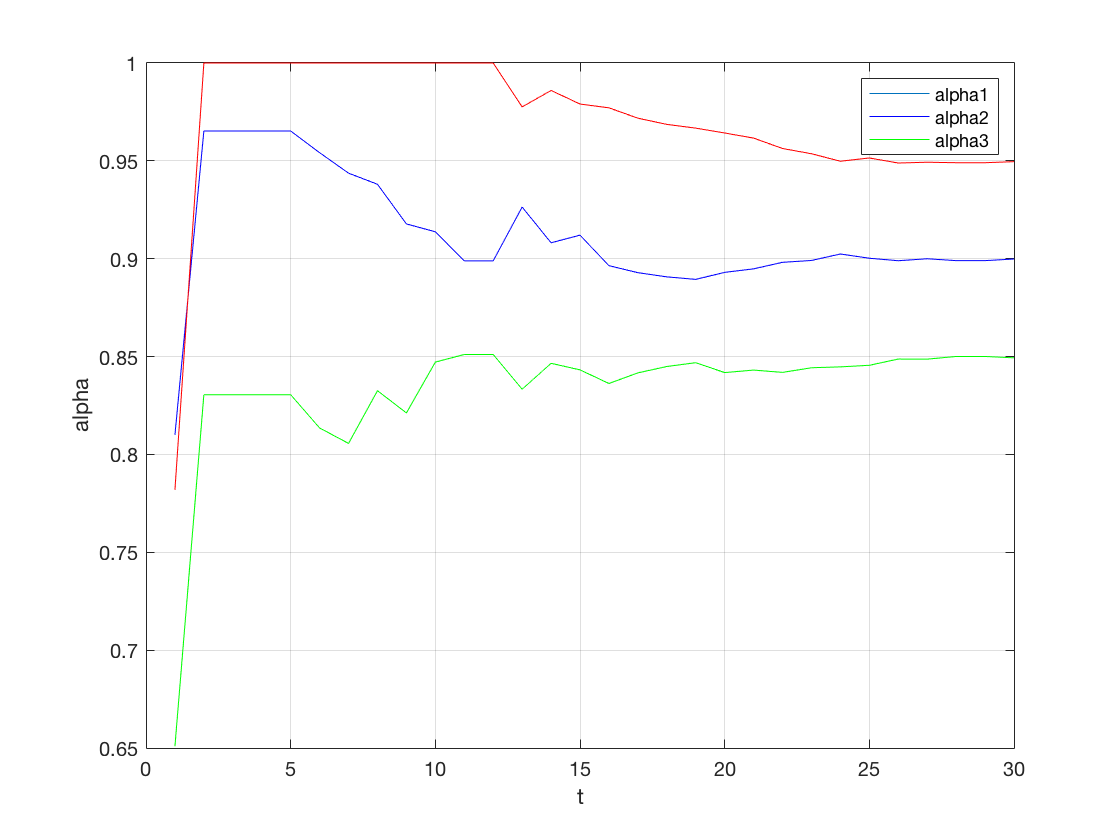

hold on 
plot(globalbest_x_result(1:k,1),'b-')
plot(globalbest_x_result(1:k,2),'g-')
plot(globalbest_x_result(1:k,3),'r-')
legend('alpha1','alpha2','alpha3');
xlabel('t');
ylabel('alpha');
grid on;

toc;

Elapsed time is 7898.300054 seconds.



%Value1=1/globalbest_faval-1; Value1=num2str(Value1);
% strcat指令可以实现字符的组合输出
%disp(strcat('the maximum value','=',Value1));

the maximum value=5.1985


%输出最大值所在的横坐标位置
%Value2=globalbest_x; Value2=num2str(Value2);
%disp(strcat('the corresponding coordinate','=',Value2));

the corresponding coordinate=-1.1617


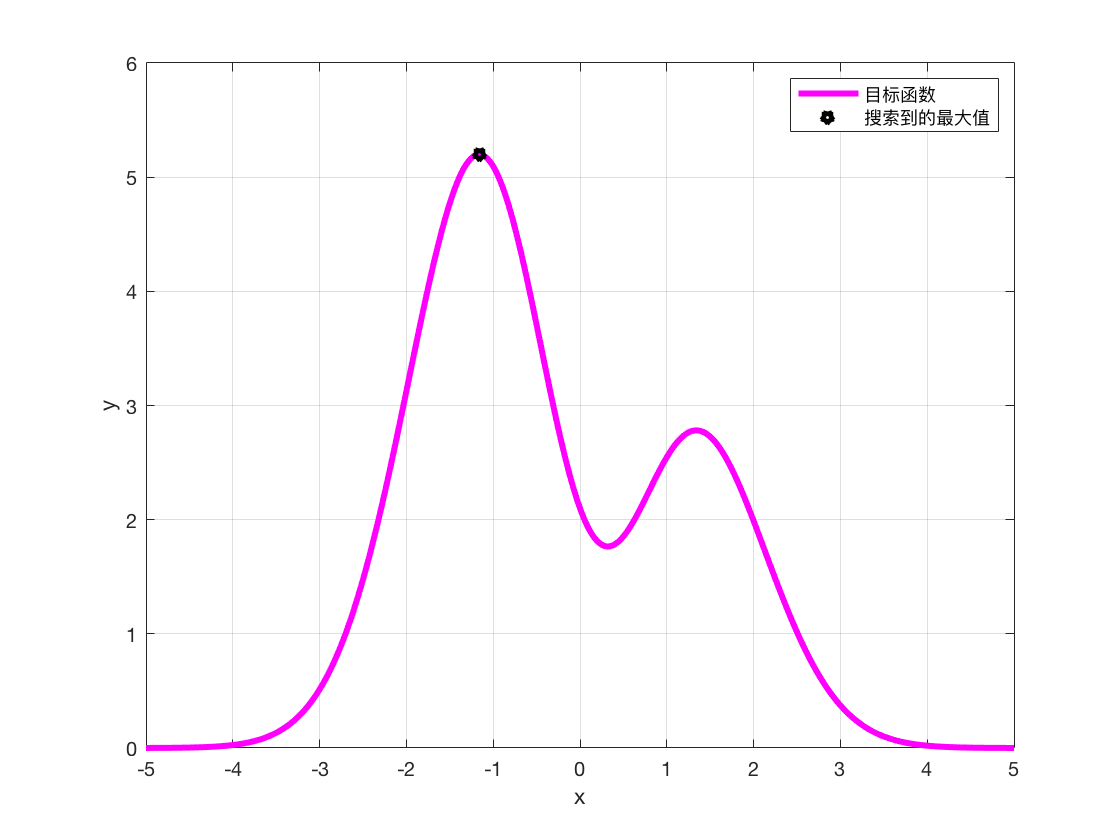

%x=t0:h:T;
%y=2.1*(1-x+2*x.^2).*exp(-x.^2/2);
%plot(x,y,'m-','linewidth',3);

%hold on;
%plot(globalbest_x,1/globalbest_faval-1,'kp','linewidth',4);
%legend('目标函数','搜索到的最大值');
%xlabel('x');
%ylabel('y');
%grid on;

%toc;

Elapsed time is 3.124696 seconds.
